**Data**

x = [5  10  15  20  25  30  35  40  45  50]

x =      5    10    15    20    25    30    35    40    45    50


y = [17  24  31  33  37  37  40  40  42  41]

y =     17    24    31    33    37    37    40    40    42    41


**Plot data**

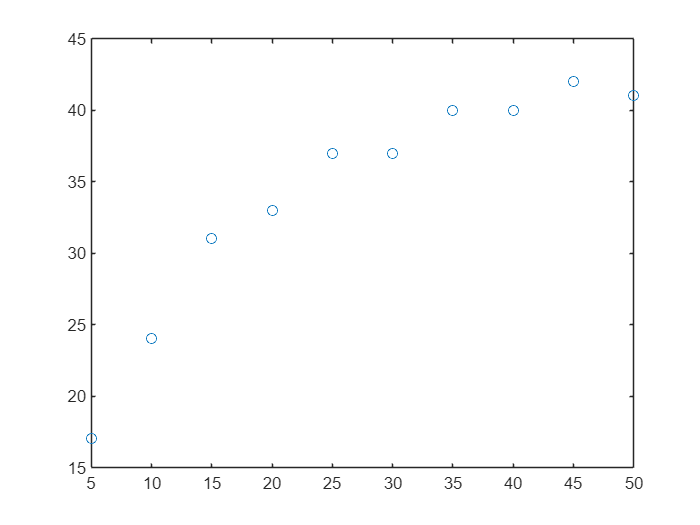

plot(x,y,"o")

**Transform data**

newx = 1./x

newx =     0.2000    0.1000    0.0667    0.0500    0.0400    0.0333    0.0286    0.0250    0.0222    0.0200


newy = 1./y

newy =     0.0588    0.0417    0.0323    0.0303    0.0270    0.0270    0.0250    0.0250    0.0238    0.0244


**Perform linear regression & plot dataset + fitted line**

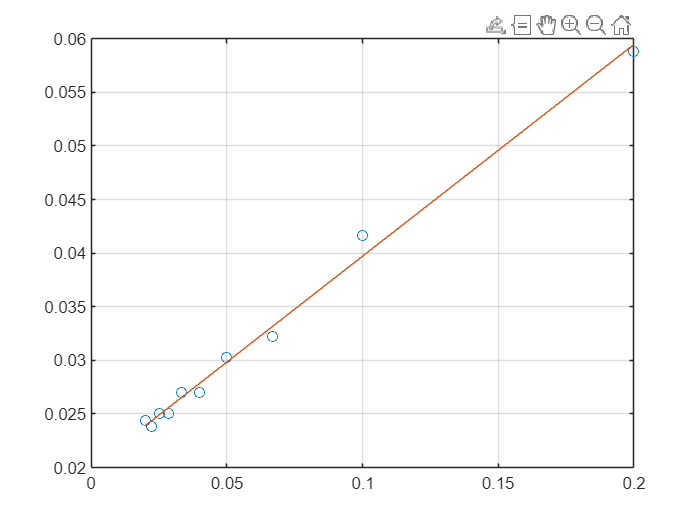

a =     0.1975    0.0200


r2 = 0.9935

[a,r2] = linregr(newx,newy)

**Computer parameters of nonlinear equation from the fitted line**

alpha = 1./a(2)

alpha = 50.0921

beta = a(1)*alpha

beta = 9.8914

**Plot the original data with the best fit nonlinear curve**

xx = 5 : 0.1 : 50

xx =     5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000    6.0000    6.1000    6.2000    6.3000    6.4000    6.5000    6.6000    6.7000    6.8000    6.9000    7.0000    7.1000    7.2000    7.3000    7.4000    7.5000    7.6000    7.7000    7.8000    7.9000    8.0000    8.1000    8.2000    8.3000    8.4000    8.5000    8.6000    8.7000    8.8000    8.9000    9.0000    9.1000    9.2000    9.3000    9.4000    9.5000    9.6000    9.7000    9.8000    9.9000


yy = alpha .* xx./(beta+xx)

yy =    16.8192   17.0411   17.2601   17.4763   17.6896   17.9001   18.1079   18.3130   18.5155   18.7155   18.9130   19.1079   19.3005   19.4907   19.6785   19.8640   20.0473   20.2284   20.4073   20.5841   20.7588   20.9315   21.1021   21.2707   21.4374   21.6021   21.7650   21.9261   22.0853   22.2427   22.3983   22.5523   22.7045   22.8550   23.0040   23.1512   23.2969   23.4411   23.5836   23.7247   23.8643   24.0024   24.1390   24.2743   24.4081   24.5406   24.6717   24.8014   24.9298   25.0570


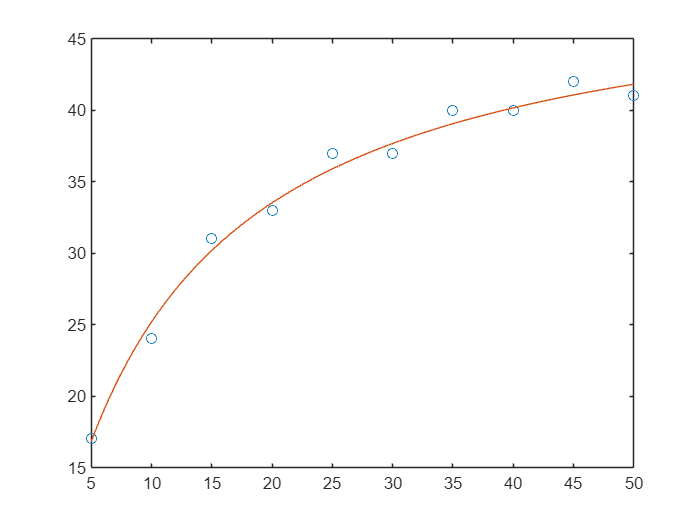


plot(x, y,'o',xx,yy,'-')

**Predict the value of y for the given x**

xtest = 45

xtest = 45


predict_y = alpha * xtest/(beta+xtest)

predict_y = 41.0656